clear;
close all;

[files, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\*.mat', ...
    'Select files','MultiSelect','on');

if ischar(files)
    files = {files};
end

allData = struct();

count = 0

count = 0

for i = 1:numel(files)
    fname = fullfile(path, files{i});

    % Find the threshSum-like variable name
    info = whos('-file', fname);
    matchIdx = find(contains({info.name}, 'threshSum', 'IgnoreCase', true), 1);

    if isempty(matchIdx)
        warning('No variable containing "threshSum" in %s', files{i});
        continue
    end

    varname = info(matchIdx).name;
    S = load(fname, varname);
    data = S.(varname);      % struct from this file

    fList = fieldnames(data);

    for f = 1:numel(fList)
        oldFld = fList{f};
        count = count +1;

        % ---- POSTFIX: add file index at the end ----
        newFld = sprintf('%s_%02d', oldFld, count);

        % If name still collides (very rare), append "_dup"
        while isfield(allData, newFld)
            newFld = [newFld '_dup'];
        end

        allData.(newFld) = data.(oldFld);
    end
end


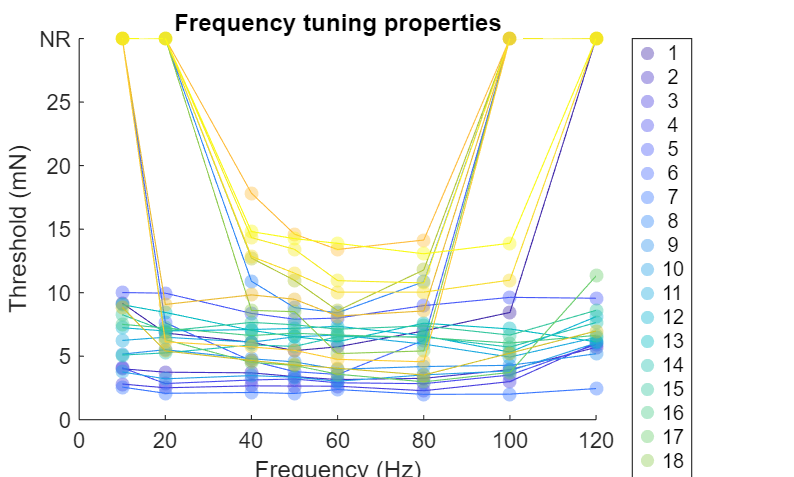

freqs = [10 20 40 50 60 80 100 120];

fi1 = figure; hold on;
fields = fieldnames(allData);

NR_value = 30;  % must match ylim top

% Define groups by index
groupPurple = [0];   % indices for purple
groupGreen  = [0]; % indices for green

colors = parula(numel(fields));
neuronIndex = zeros(length(fields),1);
Min_threshold_out = zeros(length(fields),1);

m = length(fields);
n = length(allData.(fields{1})); 
Matrix = zeros(m,n);
for i = 1:length(fields)
    data = allData.(fields{i}) * 50;
    
    if length(data) ~= length(freqs)
        continue
    end
    tokens = regexp(fields{i}, '(\d+)$', 'tokens');
    neuronIndex(i) = str2double(tokens{1}{1});
    dataNR = data;
    dataNR(isnan(dataNR)) = NR_value;
    Matrix(i, :) = dataNR;

    Min_threshold_out(i)= min(dataNR);

    c = colors(i, :);
        scatter(freqs, dataNR, 40, c, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8, ...
        'DisplayName', fields{i}(end));
    plot(freqs, dataNR, '-', 'Color', c,'HandleVisibility', 'off'); 
    % Pick color depending on group index
    % if ismember(i, groupPurple)
    %     c = [0.5 0 0.5];  % purple
    % elseif ismember(i, groupGreen)
    %     c = [0 0.6 0];    % green
    % else
    %     c = [0.7 0.7 0.7]; % fallback: gray
    % end

    % plot(freqs(1:numel(dataNR)), dataNR, 'o-', ...
    %     'Color', c, 'MarkerFaceColor', c, ...
    %     'DisplayName', fields{i});
end
Mean = mean(Matrix,1)';
Std = std(Matrix,1)';
% Axis and labels
ylim([0 NR_value]);
yticks([0 5 10 15 20 25 NR_value]);
yticklabels({'0','5','10','15','20','25','NR'});
xlabel('Frequency (Hz)');
ylabel('Threshold (mN)');
title('Frequency tuning properties');
legend(num2str(neuronIndex), 'Location', 'northeastoutside');
% txt = sprintf('#neurons: %d', count);
% annotation('textbox', [0.78 0.75 0.15 0.10], ...   % [x y w h] in normalized units
%     'String', txt, ...
%     'FitBoxToText', 'on', ...
%     'EdgeColor', 'k', ...      % no border
%     'FontSize', 12, ...
%     'HorizontalAlignment', 'left');
set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'Position', [0.10 0.12 0.65 0.80]);

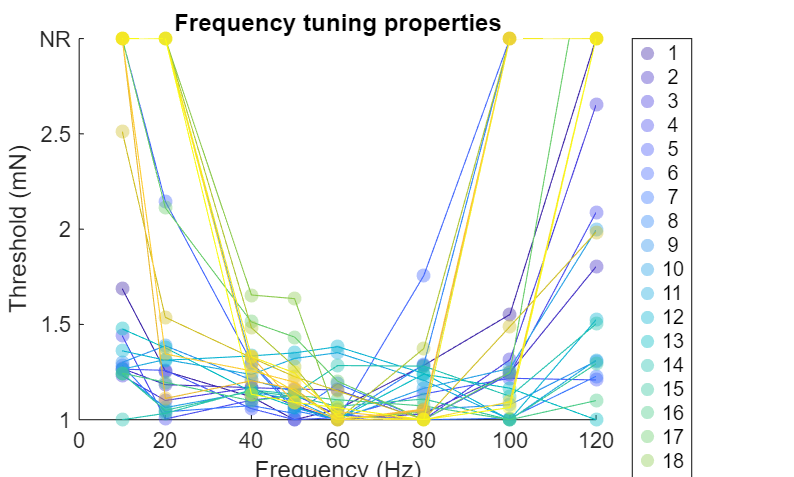


%save the min threshold
T = table(fields, Min_threshold_out, ...
          'VariableNames', {'NeuronID', 'MinThreshold'});
tableName = strcat(path,'\Min_threshold_output.csv');
% writetable(T, tableName);


%plot normalized thresholds
freqs = [10 20 40 50 60 80 100 120];

fi2 = figure; hold on;
fields = fieldnames(allData);

NR_value = 3;  % must match ylim top
y_ticks = 1:0.5:NR_value;

% Define groups by index
group1_tuned_idx   = [];
group2_untuned_idx = [];
% Parameters for grouping
tuning_threshold = 1.5;   % change this to be more/less strict
norm_alldata = struct();

colors = parula(numel(fields));
neuronIndex = zeros(length(fields),1);
for i = 1:length(fields)
    data = allData.(fields{i}) * 50;
    tokens = regexp(fields{i}, '(\d+)$', 'tokens');
    neuronIndex(i) = str2double(tokens{1}{1});
    if length(data) ~= length(freqs)
        errordlg('Wrong input data structure!')
    end
    % dataNR = data;
    % dataNR(isnan(dataNR)) = NR_value;
    min_thresh_data = min(data, [], 'omitnan');

    % If all entries are NaN or min value is 0 → skip or assign safe value
    if isempty(min_thresh_data) || isnan(min_thresh_data) || min_thresh_data == 0
        % optional: mark neuron as invalid
        dataNR = NaN(size(data));
    else
        % Normalize thresholds
        norm_thresh_data = data / min_thresh_data;
        dataNR = norm_thresh_data;
    end

    % Replace normalized NaNs with your defined NR value
    dataNR(isnan(dataNR)) = NR_value;

    tuningRange = max(dataNR) - min(dataNR);  % min should be ~1

    if tuningRange >= tuning_threshold
        % Group 1: clear frequency preference
        group1_tuned_idx(end+1) = i;
    else
        % Group 2: no strong preference
        group2_untuned_idx(end+1) = i;
    end
    c = colors(i, :);
        scatter(freqs, dataNR, 40, c, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8, ...
        'DisplayName', fields{i}(end));
    plot(freqs, dataNR, '-', 'Color', c,'HandleVisibility', 'off'); 
    % Pick color depending on group index
    % if ismember(i, groupPurple)
    %     c = [0.5 0 0.5];  % purple
    % elseif ismember(i, groupGreen)
    %     c = [0 0.6 0];    % green
    % else
    %     c = [0.7 0.7 0.7]; % fallback: gray
    % end

    % plot(freqs(1:numel(dataNR)), dataNR, 'o-', ...
    %     'Color', c, 'MarkerFaceColor', c, ...
    %     'DisplayName', fields{i});
    norm_alldata.(fields{i}) = dataNR;
end

% Axis and labels
ylim([1 NR_value]);
yticks(y_ticks);
yticklabels([string(y_ticks(1:end-1)), "NR"]);
xlabel('Frequency (Hz)');
ylabel('Threshold (mN)');
title('Frequency tuning properties');
legend(num2str(neuronIndex), 'Location', 'northeastoutside');
% txt = sprintf('#neurons: %d', count);
% annotation('textbox', [0.78 0.75 0.15 0.10], ...   % [x y w h] in normalized units
%     'String', txt, ...
%     'FitBoxToText', 'on', ...
%     'EdgeColor', 'k', ...      % no border
%     'FontSize', 12, ...
%     'HorizontalAlignment', 'left');
set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'Position', [0.10 0.12 0.65 0.80]); 

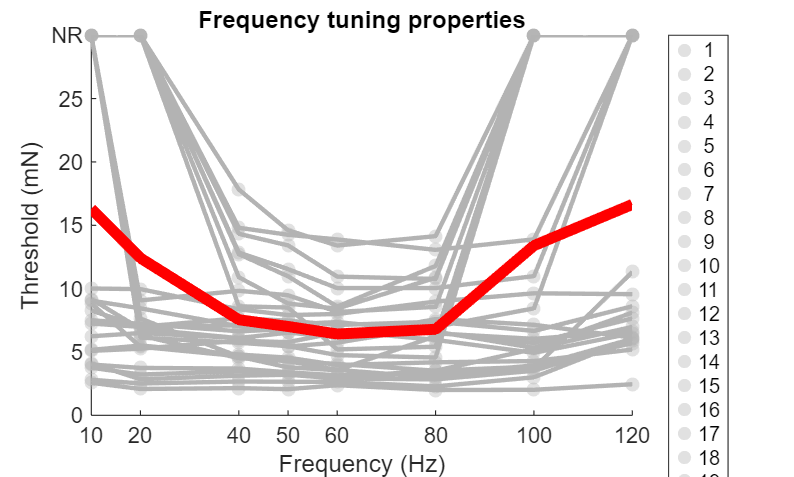


%Plot all and mean
allStatsData = NaN(numel(fields), numel(freqs));
NR_value = 30; 
fi3 = figure; hold on;
for i = 1:length(fields)
    data = allData.(fields{i}) * 50;
    
    if length(data) ~= length(freqs)
        continue
    end

    dataNR = data;
    
    dataNR(isnan(dataNR)) = NR_value;
    allStatsData(i,:) = dataNR;
    scatter(freqs, dataNR, 40, [.7 .7 .7], 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8, ...
        'DisplayName', fields{i}(end));
    plot(freqs, dataNR, '-', 'Color', [.7 .7 .7],'LineWidth',2,'HandleVisibility', 'off'); 
    % Pick color depending on group index
    % if ismember(i, groupPurple)
    %     c = [0.5 0 0.5];  % purple
    % elseif ismember(i, groupGreen)
    %     c = [0 0.6 0];    % green
    % else
    %     c = [0.7 0.7 0.7]; % fallback: gray
    % end

    % plot(freqs(1:numel(dataNR)), dataNR, 'o-', ...
    %     'Color', c, 'MarkerFaceColor', c, ...
    %     'DisplayName', fields{i});
end
plot(freqs, mean(allStatsData,1,'omitnan'), '-','Color', 'r','LineWidth',5, 'DisplayName','All mean');
g1_tuned_mean = mean(allStatsData(group1_tuned_idx,:),1);
g2_untuned_mean = mean(allStatsData(group2_untuned_idx,:),1);

%plot(freqs,g1_tuned_mean, '-','Color','magenta','LineWidth',3, 'DisplayName','Tuned mean');
%plot(freqs,g2_untuned_mean, '-','Color','blue','LineWidth',3, 'DisplayName','Untuned mean');


% Axis and labels
ylim([0 NR_value]);
xlim([freqs(1),freqs(end)]);
yticks([0 5 10 15 20 25 NR_value]);
yticklabels({'0','5','10','15','20','25','NR'});
xticks(freqs);
xlabel('Frequency (Hz)');
ylabel('Threshold (mN)');
title('Frequency tuning properties');
legend(num2str(neuronIndex),'Location', 'northeastoutside');
set(gcf, 'Position', [100 100 1000 600]); 

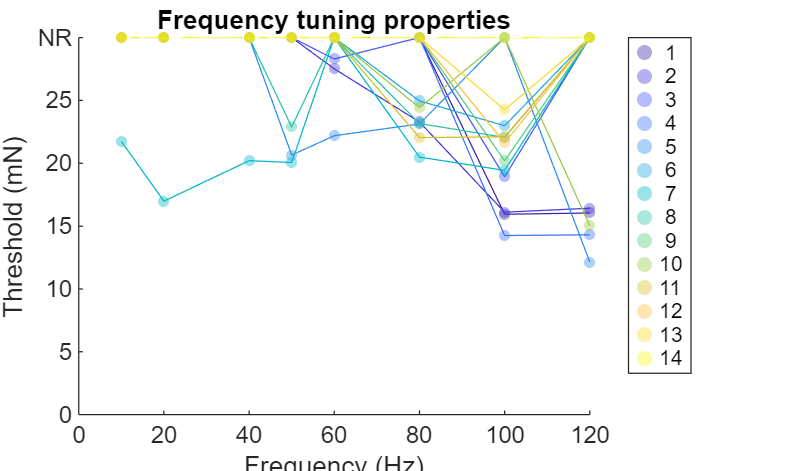

figureName_allneuron = strcat(path,"\CombinedFrequencytuning.pdf");
exportgraphics(fi1, figureName_allneuron,"Resolution",300);

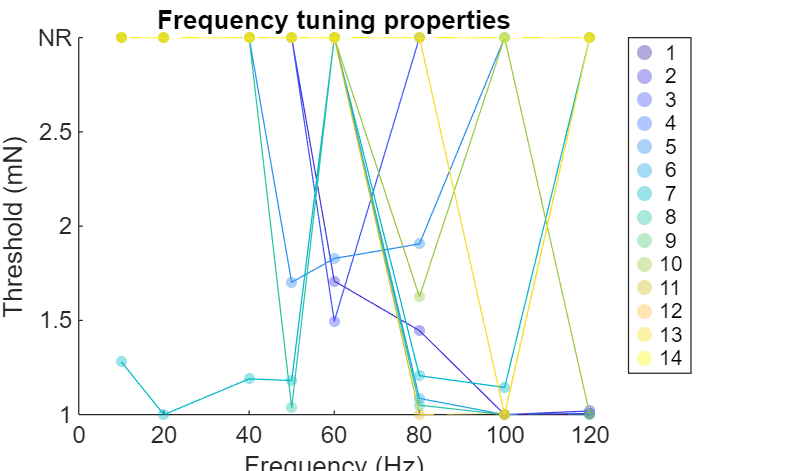

figureName_allneuron_norm = strcat(path,"\CombinedFrequencytuning_normalized.pdf");
exportgraphics(fi2, figureName_allneuron_norm,"Resolution",300);

figureName_allneuron_mean = strcat(path,"\CombinedFrequencytuning_mean.pdf");
exportgraphics(fi3, figureName_allneuron_mean,"Resolution",300);
[~, folderName] = fileparts(fileparts(path));
MatrixName_allneuron = strcat(path,folderName,"_CombinedFrequencytuning.mat");
save(MatrixName_allneuron, 'Matrix');

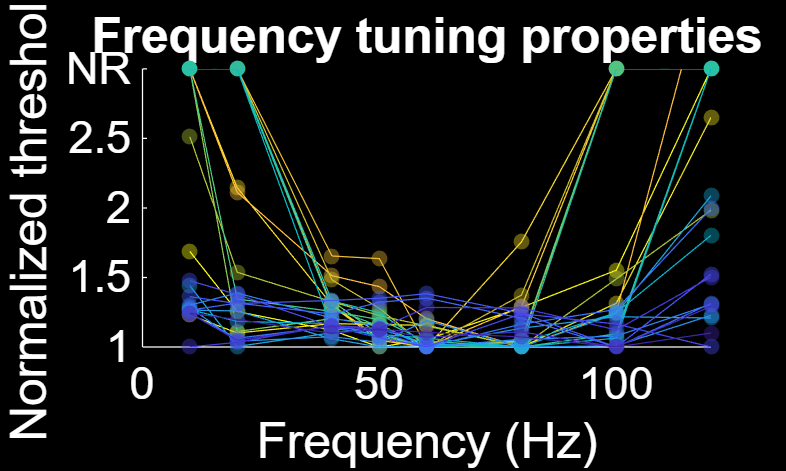

%reorder the neurons for gif
loopOrder = [group1_tuned_idx, group2_untuned_idx];
colors = flipud(parula(numel(loopOrder)));
fields = fieldnames(norm_alldata);
fi2 = figure; hold on;

% static axes & labels
NR_value = 3;
y_ticks = 1:0.5:NR_value;
ylim([1 NR_value]);
yticks(y_ticks);
yticklabels([string(y_ticks(1:end-1)), "NR"]);
xlabel('Frequency (Hz)', 'FontSize', 20);
ylabel('Normalized threshold', 'FontSize', 20);
title('Frequency tuning properties', 'FontSize', 24);

set(gcf, 'Position', [100 100 1000 600]); 
%set(gca, 'Position', [0.10 0.12 0.65 0.80]);
set(gca, 'FontSize', 18);

%dark background
set(gcf, 'Color', 'k');
set(gca, 'Color', 'k');
set(gca, 'XColor', 'w');
set(gca, 'YColor', 'w');
set(gca, 'GridColor', 'w');
title('Frequency tuning properties', 'Color', 'w');
xlabel('Frequency (Hz)', 'Color', 'w');
ylabel('Normalized threshold', 'Color', 'w');

color_tuned   = [0 0.6 0];   % group 1
color_untuned = [0.5 0 0.5]; % group 2



gifFile = strcat(path,'normalized_freq_tuning_grouped.gif');

for k = 1:numel(loopOrder)
    i = loopOrder(k);

    % choose color by group
    % if ismember(i, group1_tuned_idx)
    %     thisColor = color_tuned;
    % else
    %     thisColor = color_untuned;
    % end
    thisColor = colors(k,:);

    vals = norm_alldata.(fields{i});  % already includes NR_value where needed

    scatter(freqs, vals, 40, thisColor, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8);
    plot(freqs, vals, '-', 'Color', thisColor, 'HandleVisibility', 'off');

    % ----- add frame to GIF -----
    drawnow;
    frame      = getframe(fi2);
    [imind,cm] = rgb2ind(frame2im(frame), 256);

    if k == 1
        imwrite(imind, cm, gifFile, 'gif', ...
            'Loopcount', inf, ...
            'DelayTime', 0.4);
    elseif ismember(i, group1_tuned_idx)
        imwrite(imind, cm, gifFile, 'gif', ...
            'WriteMode', 'append', ...
            'DelayTime', 0.4);
    end
end
figureName_allneuron_norm = strcat(path,"\CombinedFrequencytuning_normalized_Gif.png");
exportgraphics(fi2, figureName_allneuron_norm,"Resolution",300,"BackgroundColor", "k");
hold off;

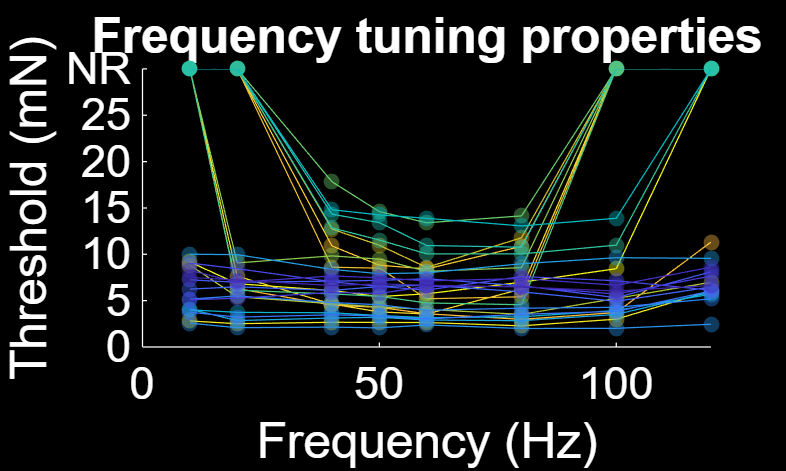


% raw threshold
NR_value = 30;
fi3 = figure; hold on;

% y-axis for raw thresholds (example: 0–30 with NR at 30)
yticks_raw = [0 5 10 15 20 25 NR_value];
ylim([0 NR_value]);
yticks(yticks_raw);
yticklabels([string(yticks_raw(1:end-1)), "NR"]);
xlabel('Frequency (Hz)', 'FontSize', 20);
ylabel('Threshold (mN)', 'FontSize', 20);
title('Frequency tuning properties', 'FontSize', 24);

set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'FontSize', 18);

%dark background
set(gcf, 'Color', 'k');
set(gca, 'Color', 'k');
set(gca, 'XColor', 'w');
set(gca, 'YColor', 'w');
set(gca, 'GridColor', 'w');
title('Frequency tuning properties', 'Color', 'w');
xlabel('Frequency (Hz)', 'Color', 'w');
ylabel('Threshold (mN)', 'Color', 'w');

gifFile2 = fullfile(path, 'freq_tuning_grouped.gif');

for k = 1:numel(loopOrder)
    i = loopOrder(k);
    thisColor = colors(k,:);   % same color assignment as normalized GIF

    raw_vals = allData.(fields{i}) * 50;    % or whatever scaling you use
    vals = raw_vals;
    vals(isnan(vals)) = NR_value;           % show NR as top value

    scatter(freqs, vals, 40, thisColor, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8);
    plot(freqs, vals, '-', 'Color', thisColor, 'HandleVisibility', 'off');

    % ----- add frame to GIF -----
    drawnow;
    frame      = getframe(fi3);            % <--- capture fi3 here!
    [imind,cm] = rgb2ind(frame2im(frame), 256);

    if k == 1
        imwrite(imind, cm, gifFile2, 'gif', ...
            'Loopcount', inf, ...
            'DelayTime', 0.4);
    elseif ismember(i, group1_tuned_idx)
        imwrite(imind, cm, gifFile2, 'gif', ...
            'WriteMode', 'append', ...
            'DelayTime', 0.4);
    end
end

hold off;
figureName_allneuron = strcat(path,"\CombinedFrequencytuning_Gif.png");
exportgraphics(fi3, figureName_allneuron,"Resolution",300,"BackgroundColor", "k");

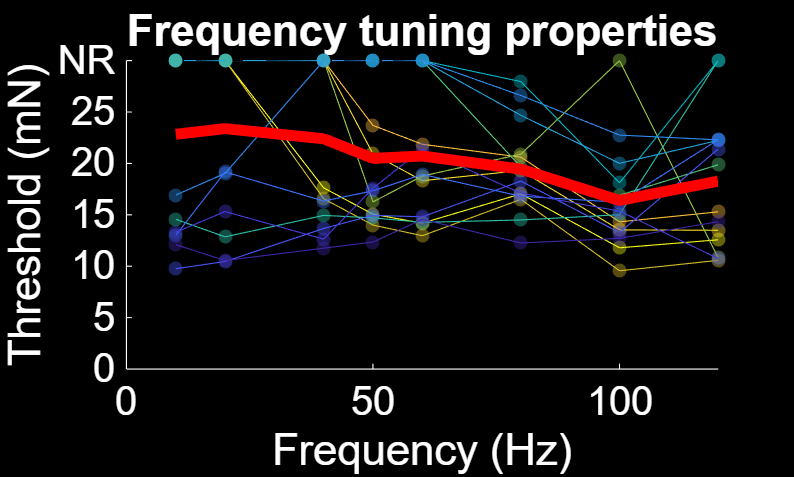

%Everything with mean
NR_value = 30;
loopOrder = [group1_tuned_idx, group2_untuned_idx];
colors = flipud(parula(numel(loopOrder)));
fi5 = figure; hold on;

% y-axis for raw thresholds (example: 0–30 with NR at 30)
yticks_raw = [0 5 10 15 20 25 NR_value];
ylim([0 NR_value]);
yticks(yticks_raw);
yticklabels([string(yticks_raw(1:end-1)), "NR"]);
xlabel('Frequency (Hz)', 'FontSize', 20);
ylabel('Threshold (mN)', 'FontSize', 20);
title('Frequency tuning properties', 'FontSize', 24);

set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'FontSize', 18);

%dark background
set(gcf, 'Color', 'k');
set(gca, 'Color', 'k');
set(gca, 'XColor', 'w');
set(gca, 'YColor', 'w');
set(gca, 'GridColor', 'w');
title('Frequency tuning properties', 'Color', 'w');
xlabel('Frequency (Hz)', 'Color', 'w');
ylabel('Threshold (mN)', 'Color', 'w');

for k = 1:numel(loopOrder)
    i = loopOrder(k);
    thisColor = colors(k,:);   % same color assignment as normalized GIF

    raw_vals = allData.(fields{i}) * 50;    % or whatever scaling you use
    vals = raw_vals;
    vals(isnan(vals)) = NR_value;           % show NR as top value

    scatter(freqs, vals, 40, thisColor, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8);
    plot(freqs, vals, '-', 'Color', thisColor, 'HandleVisibility', 'off');
end
plot(freqs, mean(allStatsData,1,'omitnan'), '-','Color', 'r','LineWidth',5);
figureName_allneuron = strcat(path,"\CombinedFrequencytuning_Gif_withMean.png");
exportgraphics(fi5, figureName_allneuron,"Resolution",300,"BackgroundColor", "k");

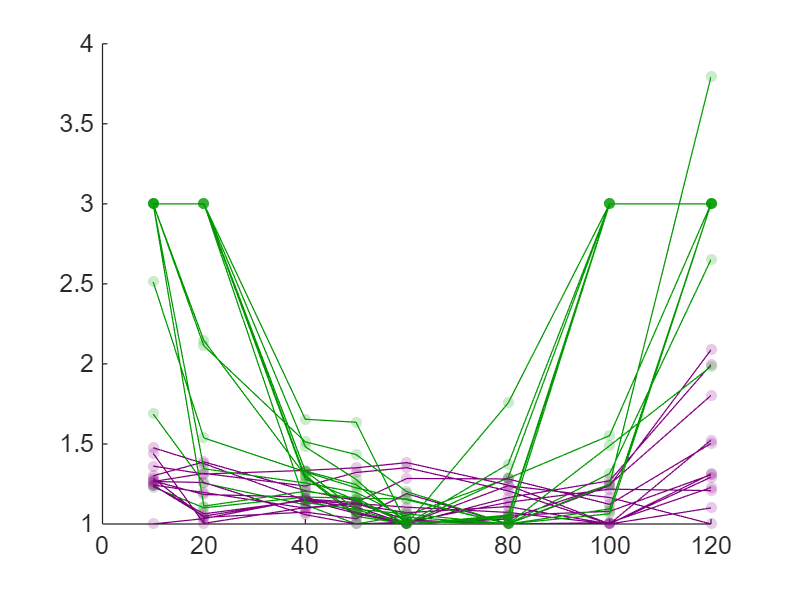


% plot normalized thresholds NOT USED
freqs = [10 20 40 50 60 80 100 120];

fi2 = figure; hold on;
fields = fieldnames(allData);

NR_value = 3;  % must match ylim top
y_ticks = 1:0.5:NR_value;

% Parameters for grouping
tuning_threshold = 1.5;   % change this to be more/less strict

% Colors for the two groups
color_tuned   = [0 0.6 0];    % green  (group 1: clear preference)
color_untuned = [0.5 0 0.5];  % purple (group 2: no clear preference)

% To store indices
group1_tuned_idx   = [];
group2_untuned_idx = [];

nNeurons = numel(fields);
nFreqs   = numel(freqs);

% Store data for statistics (NR entries will be NaN here)
allStatsData = NaN(nNeurons, nFreqs);

for i = 1:nNeurons
    data = allData.(fields{i}) * 50;
    if length(data) ~= length(freqs)
        errordlg('Wrong input data structure!')
        return
    end

    % Compute normalized thresholds
    min_thresh_data = min(data, [], 'omitnan');

    if isempty(min_thresh_data) || isnan(min_thresh_data) || min_thresh_data == 0
        norm_thresh_data = NaN(size(data));
    else
        norm_thresh_data = data / min_thresh_data;
    end

    % For plotting: replace NaNs with NR_value
    dataNR = norm_thresh_data;
    dataNR(isnan(dataNR)) = NR_value;

    % For stats: keep NaNs where NR (i.e., non-responsive)
    statsRow = norm_thresh_data;   % NaNs stay NaNs
    allStatsData(i, :) = statsRow;

    % ----- Decide group based on tuning -----
    validVals = dataNR;
    if isempty(validVals)
        % nothing to classify → put in untuned by default
        groupColor = color_untuned;
        group2_untuned_idx(end+1) = i;
    else
        tuningRange = max(validVals) - min(validVals);  % min should be ~1

        if tuningRange >= tuning_threshold
            % Group 1: clear frequency preference
            groupColor = color_tuned;
            group1_tuned_idx(end+1) = i;
        else
            % Group 2: no strong preference
            groupColor = color_untuned;
            group2_untuned_idx(end+1) = i;
        end
    end
    % ---------------------------------------

    % Plot each neuron in its group color
    scatter(freqs, dataNR, 20, groupColor, 'filled', ...
        'MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 0.5);
    plot(freqs, dataNR, '-', 'Color', groupColor, 'HandleVisibility', 'off'); 
end
hold off;

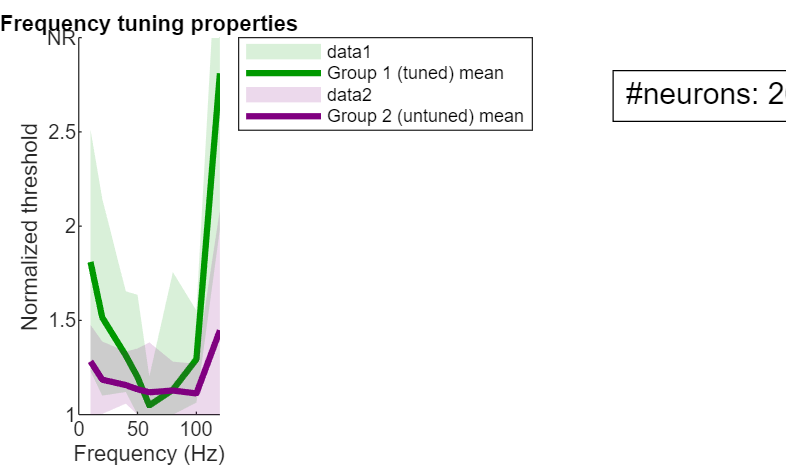

figure
hold on;



%% ====== GROUP STATISTICS AND SHADING ======
% Helper to compute mean/min/max per group
compute_group_stats = @(idx) deal( ...
    mean(allStatsData(idx, :), 1, 'omitnan'), ...
    min(allStatsData(idx, :), [], 1, 'omitnan'), ...
    max(allStatsData(idx, :), [], 1, 'omitnan') );

% Group 1 (tuned)
if ~isempty(group1_tuned_idx)
    [g1_mean, g1_min, g1_max] = compute_group_stats(group1_tuned_idx);

    % If an entire column is NaN, optionally push it to NR_value for plotting
    g1_mean_plot = g1_mean;
    g1_mean_plot(isnan(g1_mean_plot)) = NR_value;

    g1_min_plot = g1_min;
    g1_max_plot = g1_max;
    g1_min_plot(isnan(g1_min_plot)) = NR_value;
    g1_max_plot(isnan(g1_max_plot)) = NR_value;

    % Shaded area = range [min, max]
    x_patch = [freqs, fliplr(freqs)];
    y_patch = [g1_min_plot, fliplr(g1_max_plot)];
    p1 = patch(x_patch, y_patch, color_tuned, ...
        'FaceAlpha', 0.15, 'EdgeColor', 'none');

    % Mean line
    l1 = plot(freqs, g1_mean_plot, '-', ...
        'Color', color_tuned, 'LineWidth', 2.5, ...
        'DisplayName', 'Group 1 (tuned) mean');
end

% Group 2 (untuned)
if ~isempty(group2_untuned_idx)
    [g2_mean, g2_min, g2_max] = compute_group_stats(group2_untuned_idx);

    g2_mean_plot = g2_mean;
    g2_mean_plot(isnan(g2_mean_plot)) = NR_value;

    g2_min_plot = g2_min;
    g2_max_plot = g2_max;
    g2_min_plot(isnan(g2_min_plot)) = NR_value;
    g2_max_plot(isnan(g2_max_plot)) = NR_value;

    x_patch2 = [freqs, fliplr(freqs)];
    y_patch2 = [g2_min_plot, fliplr(g2_max_plot)];
    p2 = patch(x_patch2, y_patch2, color_untuned, ...
        'FaceAlpha', 0.15, 'EdgeColor', 'none');

    l2 = plot(freqs, g2_mean_plot, '-', ...
        'Color', color_untuned, 'LineWidth', 2.5, ...
        'DisplayName', 'Group 2 (untuned) mean');
end
%% ==========================================

% Axis and labels
ylim([1 NR_value]);
xlim([])
yticks(y_ticks);
yticklabels([string(y_ticks(1:end-1)), "NR"]);
xlabel('Frequency (Hz)');
ylabel('Normalized threshold');
title('Frequency tuning properties');

txt = sprintf('#neurons: %d', nNeurons);
annotation('textbox', [0.78 0.75 0.15 0.10], ...   % [x y w h] in normalized units
    'String', txt, ...
    'FitBoxToText', 'on', ...
    'EdgeColor', 'k', ...
    'FontSize', 12, ...
    'HorizontalAlignment', 'left');

set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'Position', [0.10 0.12 0.65 0.80]);  

% Legend for group means
legend('Location', 'northeastoutside');